clc
clear

syms theta1 theta2 d3 theta4
syms L1 L2
%%% Tabla_DH %%%

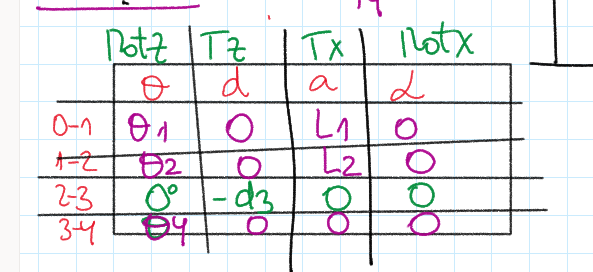

%%% Implementación_de_DH %%%
M01 = DHL(theta1,0,L1,0);
M12 = DHL(theta2,0,L2,0);
M23 = DHL(0,-d3,0,0);
M34 = DHL(theta4,0,0,0);

M04 = simplify(M01*M12*M23*M34)

$$M04 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}+\theta_{4}\right) & -\sin\left(\theta_{1}+\theta_{2}+\theta_{4}\right) & 0 & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}+\theta_{4}\right) & \cos\left(\theta_{1}+\theta_{2}+\theta_{4}\right) & 0 & L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & -d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%%% Jacobiano_Lineal %%%
Pos = [M04(1,4)
       M04(2,4)
       M04(3,4)];

theta = [theta1 theta2 d3 theta4];

J = jacobian(Pos,theta)

$$J = \left(\begin{array}{cccc} -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right) & -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right) & 0 & 0\\ L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right) & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) & 0 & 0\\ 0 & 0 & -1 & 0 \end{array}\right)$$

%%% Jacobiano_Angular %%%
z0 = [0
      0
      1];

R01 = M01(1:3,1:3);
z1 = R01(1:3,3);

z2 = [0
      0
      0];

M03 = M01*M12*M23;
R03 = M03(1:3,1:3);
z3 = R03(1:3,3);

Jw = [z0 z1 z2 z3];

J = [J
     Jw]

$$J = \left(\begin{array}{cccc} -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right) & -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right) & 0 & 0\\ L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right) & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1 \end{array}\right)$$

function M=DHL(theta,d,a,alpha)

Mrot_z = [cos(theta) -sin(theta) 0 0
          sin(theta)  cos(theta) 0 0
          0           0          1 0
          0           0          0 1];

transl = [1 0 0 a
          0 1 0 0
          0 0 1 d
          0 0 0 1];
Mrot_x = [rotx(alpha) [0;0;0]
          0 0 0        1];

M=Mrot_z*transl*Mrot_x;
end

